% Comprehensive Audio Analysis in MATLAB

% Clear workspace to avoid conflicts
clear;
clc;

% Load the audio file
[audioData, fs] = audioread('C:\Users\liono\Music\MOTOR SOUNDS\bolt 2 4th sample.wav'); % Replace with your audio file path

% Convert to mono if the audio is stereo
if size(audioData, 2) > 1
    audioData = mean(audioData, 2); % Average the two channels
end

% Display basic information
disp(['Sample Rate: ', num2str(fs), ' Hz']);

Sample Rate: 44100 Hz


disp(['Audio Duration: ', num2str(length(audioData)/fs), ' seconds']);

Audio Duration: 6.9666 seconds



% 1. Spectrogram
figure;
subplot(3, 2, 1);
spectrogram(audioData, 256, [], [], fs, 'yaxis'); % Spectrogram parameters
title('Spectrogram');
xlabel('Time (s)');
ylabel('Frequency (kHz)');
colorbar;

% 2. Amplitude Envelope Analysis
amplitudeEnvelope = abs(audioData); % Renamed variable to avoid conflict
time = (0:length(audioData)-1) / fs;
subplot(3, 2, 2);
plot(time, amplitudeEnvelope);
title('Amplitude Envelope');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% 3. Fourier Transform (FFT)
N = length(audioData); % Number of samples
frequencies = (0:N-1) * (fs/N); % Frequency vector
fftResult = abs(fft(audioData)); % Magnitude of FFT
subplot(3, 2, 3);
plot(frequencies(1:N/2), fftResult(1:N/2)); % Plot positive frequencies only

title('Fourier Transform (FFT)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

% 4. Pitch Analysis
% Clear any conflicting variable named 'pitch'
clear pitch

% Perform pitch estimation
pitchValues = pitch(audioData, fs, 'Method', 'PEF'); % Single output for pitch
timePitch = (0:length(pitchValues)-1) / fs;
subplot(3, 2, 4);
plot(timePitch, pitchValues, 'r');
title('Pitch Analysis');
xlabel('Time (s)');
ylabel('Pitch (Hz)');
grid on;

% 5. Total Harmonic Distortion (THD)
thdValue = thd(audioData, fs); % Total Harmonic Distortion
disp(['Total Harmonic Distortion (THD): ', num2str(thdValue), ' dB']);

Total Harmonic Distortion (THD): -4.333 dB



% 6. Roughness and Timbre Analysis
roughness = sum(diff(audioData).^2); % Simple roughness metric
disp(['Signal Roughness: ', num2str(roughness)]);

Signal Roughness: 3.3832



% Timbre: Spectral Centroid (proxy for timbre quality)
spectralCentroidValues = spectralCentroid(audioData, fs);
subplot(3, 2, 5);
plot((0:length(spectralCentroidValues)-1)/fs, spectralCentroidValues, 'g');
title('Spectral Centroid (Timbre)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
grid on;

% 7. Rhythm Analysis - Custom Tempo Estimation
frameLength = 1024;
hopLength = 512;

% Onset strength computation
onsetStrength = envelope(audioData, frameLength, 'rms');
timeOnsets = (0:length(onsetStrength)-1) * hopLength / fs;

% Detect peaks as beat candidates
[pks, locs] = findpeaks(onsetStrength, 'MinPeakHeight', 0.02, 'MinPeakDistance', fs/4);

% Calculate inter-beat intervals (IBIs) for tempo
IBIs = diff(locs) / fs; % Convert to seconds
if ~isempty(IBIs)
    estimatedTempo = 60 / mean(IBIs); % Tempo in BPM
    disp(['Estimated Tempo: ', num2str(estimatedTempo), ' beats per minute']);
else
    disp('No significant beats detected for tempo estimation.');
end

No significant beats detected for tempo estimation.


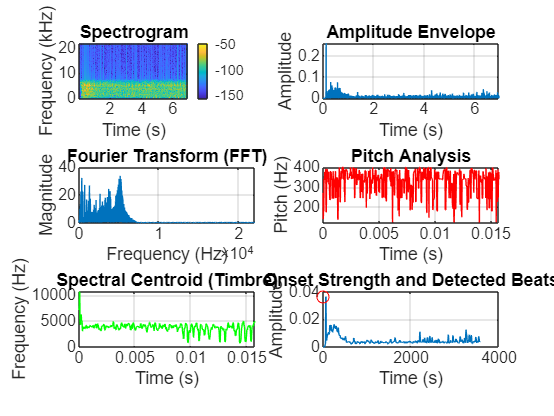


% Plot onset strength and detected beats
subplot(3, 2, 6);
plot(timeOnsets, onsetStrength);
hold on;
scatter(locs / fs, pks, 'r');
title('Onset Strength and Detected Beats');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;


% Display Summary
disp(['Signal Duration: ', num2str(length(audioData)/fs), ' seconds']);

Signal Duration: 6.9666 seconds
